close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([0,5],1000,[-250,250],1000);

定义基带信号

g = 3*cos(10*t)+2*cos(20*t);

调制

f = g.*cos(100*t);

解调：先乘以载波，再理想低通滤波（变到频域，保留基带能量，再逆变换）

g0 = f.*cos(100*t);
G0 = FT*g0;
H = (omg<30&omg>-30);
G1 = G0.*H;
g1 = IFT*G1;

分别计算基带信号和调制信号的频谱

G = FT*g;
F = FT*f;

绘图

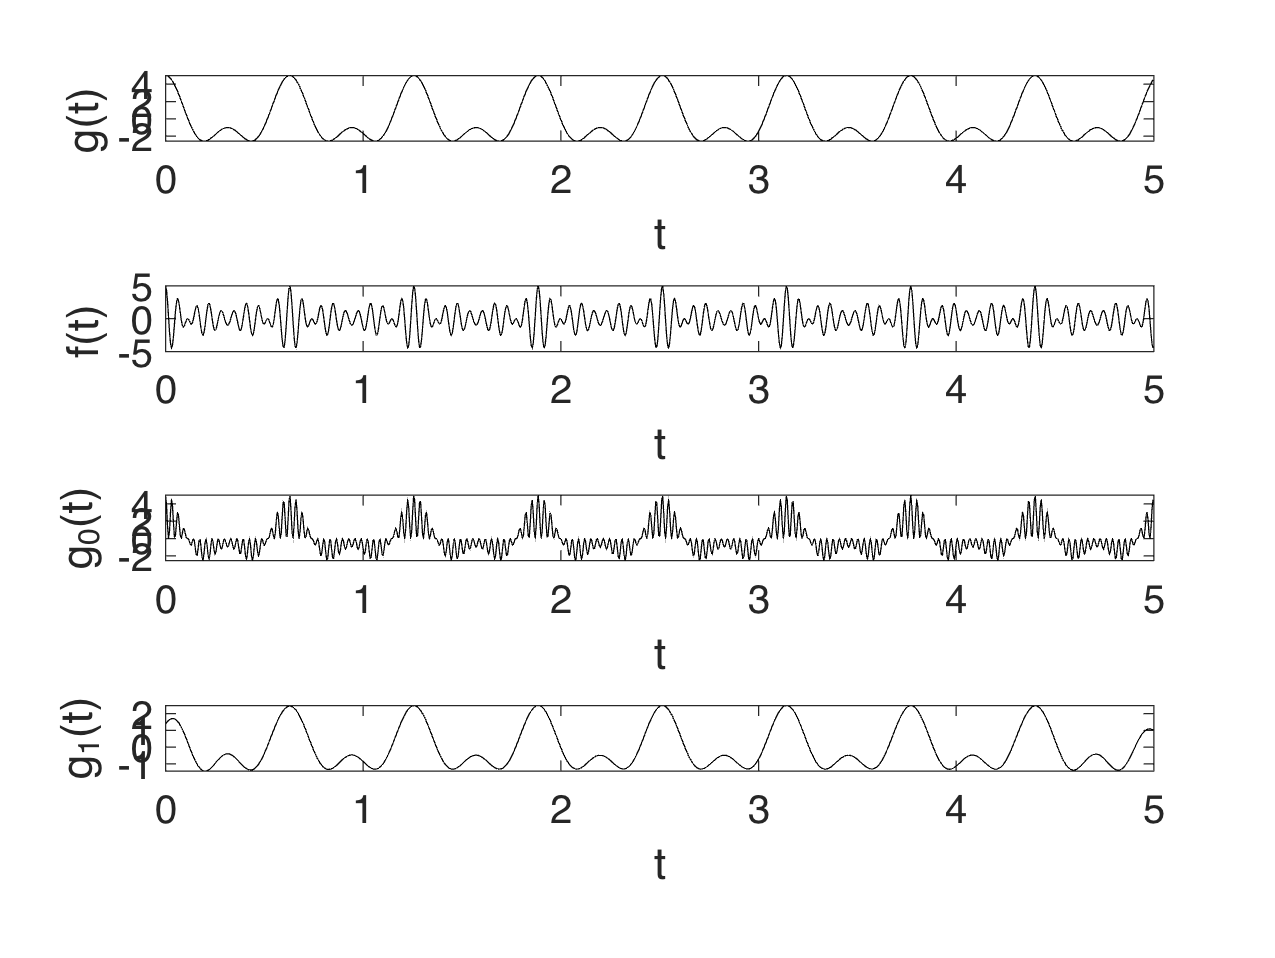

figure;
dat = [g,f,g0,g1];
txt = ['g(t)  ';'f(t)  ';'g_0(t)';'g_1(t)'];
for n = 1:4
    subplot(4,1,n), hold on, box on;
    plot(t,real(dat(:,n)),'k-');
    set(gca,'FontSize',16);
    xlabel('t'); ylabel(txt(n,:));
end


figure;
dat = [G,F,G0,H,G1];
rng = [-2,8;-1,4;-1,4;-0.5,1.5;-1,4];
txt = ['G(\omega)  ';'F(\omega)  ';'G_0(\omega)';'H(\omega)  ';'G_1(\omega)'];
for n = 1:5
    subplot(5,1,n), hold on, box on;
    plot(omg,real(dat(:,n)),'k-');
    set(gca,'FontSize',14,'XLim',[-250,250],'YLim',rng(n,:));
    xlabel('\omega');ylabel(txt(n,:));
end